# Resonator Modeling

## Initial Request

*Would this time work for you for a quick call regarding a model Remi is working on?*

*He is facing some issues with algebraic loops, and we would like your help if possible. The model relies on the following equation: *

*It works fine in both continuous and discrete mode, but as soon as we get rid of the algebraic loop (with delays for instance) the model stops behaving correctly.*

## Simple Example

### Continuous system

Let's start with the simple classic mass-spring damper


$$m\ddot{x} +c\dot{x} +\textrm{cx}=F$$


In Simulink, this looks like this:

mdl = 'massSpringDamperContinuous';
open_system(mdl);

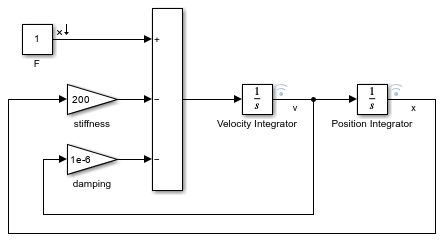

On purpose, I pick coefficients that makes the system close to instability. Let's simulate:

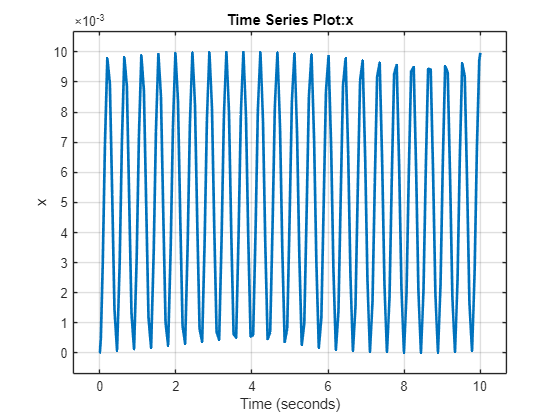

out = sim(mdl);
figure
plot(out.logsout.get('x').Values)

### Discrete system

The first "intuitive" way to convert a system like that from continuous to discrete is to replace the Integrator block with [Discrete-Time Integrator](https://www.mathworks.com/help/simulink/slref/discretetimeintegrator.html) blocks.

mdl = 'massSpringDamperDiscrete';
open_system(mdl);

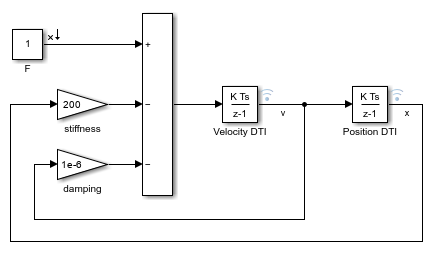

Simulating this model, we see quite different results. The system is unstable. 

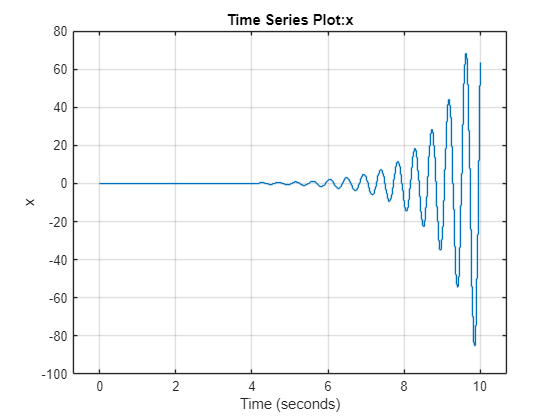

out = sim(mdl);
figure
plot(out.logsout.get('x').Values)

Note that the larger the step size is, the more unstable the system is.

### Explanation

The continuous Integrator is able to take minor steps to calculate the ideal solution. With the Discrete-Time Integrator, it can take steps only at the major steps.

The Discrete-Time Integrator has 3 methods:

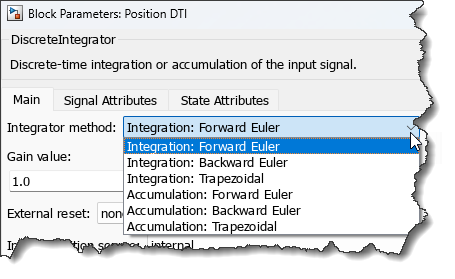

The equations for each method is:

Forward Euler method:

`         y(n)   = x(n)`

`         x(n+1) = x(n) + K*T*u(n)`

Backward Euler method:

`          y(n)   = x(n) + K*T*u(n)`

`          x(n+1) = y(n)`

Trapezoidal method: 

`          y(n)   = x(n) + K*T/2*u(n)`

`          x(n+1) = y(n) + K*T/2*u(n)`

For a simple sine wave, the results are:

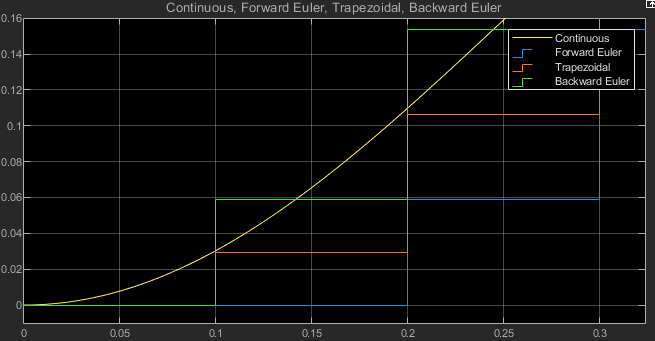

### Continuous to Discrete Conversion

It is possible to simulate a marginally stable oscillating system in Simulink. It just cannot be done by simply replace continuous by discrete-time integrator. In MATLAB, the Control system Toolbox offers a function for that: [`c2d`](https://www.mathworks.com/help/control/ref/dynamicsystem.c2d.html).

To do that, the first thing to do is to bring the system in MATLAB. For this simple system, it is straightforward:

sys = tf(1,[1 1e-6 200]);

For more complex systems, it's easier to linearize

mdl = 'massSpringDamperContinuous';
io = getlinio(mdl);
sys = tf(linearize(mdl,io))


sys =
 
  From input "F" to output "x":
           1
  -------------------
  s^2 + 1e-06 s + 200
 
Continuous-time transfer function.
Model Properties


Once the system is  linearized, it can be discretized

sysd = c2d(sys,0.01)


sysd =
 
  From input "F" to output "x":
  4.992e-05 z + 4.992e-05
  -----------------------
     z^2 - 1.98 z + 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


We can then use the results in Simulink:

mdl = 'massSpringDamperC2D';
open_system(mdl);

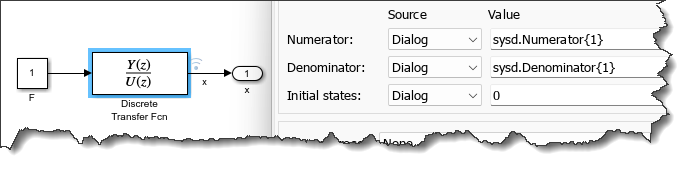

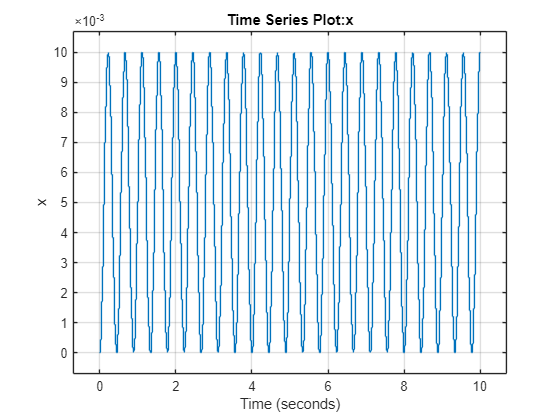

out = sim(mdl);
figure
plot(out.logsout.get('x').Values)

Additional info: [Continuous-Discrete Conversion Methods](https://www.mathworks.com/help/control/ug/continuous-discrete-conversion-methods.html)